# **Проектная работа**

## Моделирование робота с трансформируемыми колёсами, обеспечивающими возможность преодолевать препятствия

### Преподаватель - Борисов И.И.

#### Студенты - Миргазов Э., Топольницкий А.

#### Цель проекта:

Цель проекта – моделирование двухколёсного робота, колёса которого имеют возможность раскрываться и преодолевать небольшие препятствия.

#### Задачи:

Для достижения поставленной цели необходимо решить следующие задачи:

- Построить модель колеса, корпуса, вала и хвостового стабилизатора исследуемого робота;

- Построить окружение с препятствием для робота;

- Задание системы управления для управления движением робота по заданной траектории: подъезд к препятствию, раскрытие колёс, преодоление препятствия, закрытие колёс,последующее движение;

- Моделирование контакта;

- Определить максимальные размеры препятствия, которое робот может преодолеть.

**Ход работы:**

Диаметр колеса - 785 мм;

Длина первого звена - 250 мм;

Длина второго звена - 360 мм;

Ширина и высота каждого звена - 25 мм;

Ширина центрального звена - 50 мм;

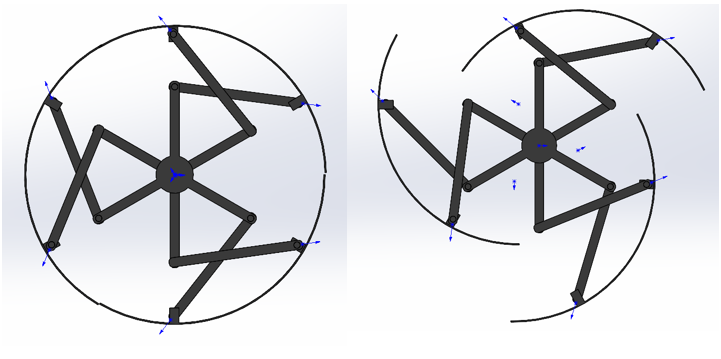

После сборки с валом, обеспечивающим движение, и центральным телом, модель выглядит следующим образом

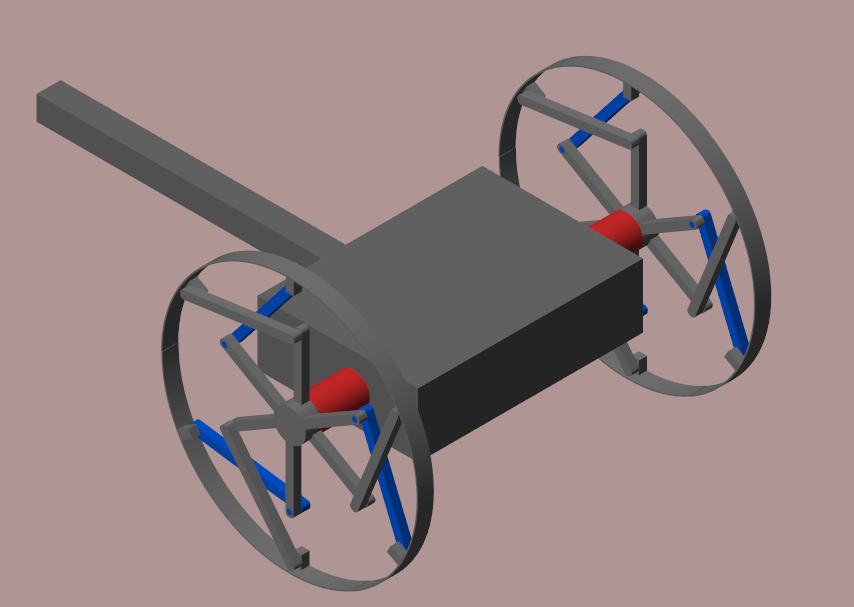

h0 = [60 70 80 90 95 100 110 120 125 130 140 150 160 170 180 190 200 205 210];

h = 205; % мм, задание высоты ступеньки
w = 650; % мм, задание ширины ступеньки
c_st_fr = 0.3; % коэффициент статического трения
c_dyn_fr = 0.3; % коэффициент динамического трения

kp_w = 100; % коэффициенты ПИД-регулятора
ki_w = 100;
kd_w = 100;



Project_sb

out = sim('Project_sb.slx')

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   sens: [1x1 struct] 
                   tout: [82188x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


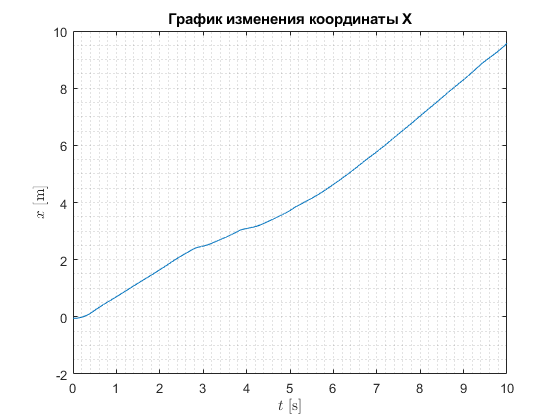

figure;
plot(out.sens.x.time, out.sens.x.data)
grid minor
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('График изменения координаты Х')

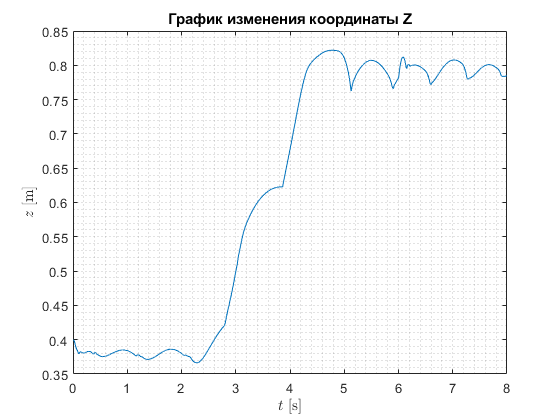

figure;
plot(out.sens.z.time, out.sens.z.data)
grid minor
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$z$ [m]','Interpreter',"latex")
title('График изменения координаты Z')
xlim([0, 8])

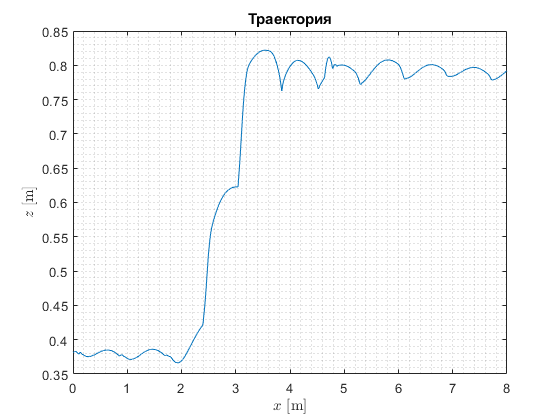

figure;
plot(out.sens.x.data,out.sens.z.data)
xlim([0,8])
grid minor
xlabel('$x$ [m]','Interpreter',"latex")
ylabel('$z$ [m]','Interpreter',"latex")
title('Траектория')

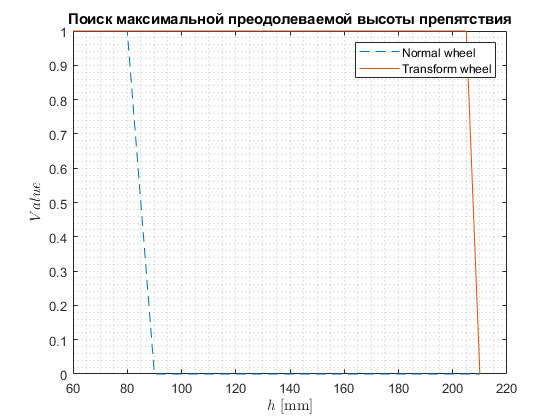


normal_wheel = [1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
cool_wheel = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0];
figure;
plot(h0,normal_wheel, 'LineStyle','--')
hold on
plot(h0,cool_wheel)
xlabel('$h$ [mm]','Interpreter',"latex")
ylabel('$Value$','Interpreter',"latex")
title('Поиск максимальной преодолеваемой высоты препятствия')
grid minor
legend('Normal wheel','Transform wheel')

    По графику выше видно, что при использовании трансформируемого колеса, робот получает возможность преодолевать препятствия на 125 мм, или 12,5 см, выше, чем при использовании обычного колеса. Максимальная преодолеваемая высота с обычным колесом - 8 см, с трансформируемым - 20,5 см.